`参考DR_CAN B站讲解视频：``https://space.bilibili.com/230105574/channel/seriesdetail?sid=2391534`

`在PID_controller中所使用的二阶系统为：`


$$\dot{x}=Ax+Bu$$


$\omega_n=1, \zeta=0.5, 系统的两个极点为:\lambda_1=-\zeta\omega_n+j\omega_n\sqrt{1-\zeta^2}, \lambda_2=-\zeta\omega_n-j\omega_n\sqrt{1-\zeta^2}$，假设$y =Cx, C=I

$。

MPC控制中多使用数位控制，因此系统状态方程由微分方程转换为差分方程(使用前向欧拉法)，采样时间h设为0.01s：


$$x_{k+1}=Ax_{k}+Bu_{k}
\\ y_{k}=Cx_{k}+Du_{k}$$


即：


$$\\ x1_{k+1}=x2_{k}
\\ x2_{k+1}=-\omega_n^2x1_{k}-2\zeta\omega_nx2_{k}+\omega_n^2u_2$$


clc
clear
close all
warning off

% 定义仿真步长
h = 0.01;
% 定义被控系统
global Wn zeta
Wn = 1;         % 固有频率 1rad/s
zeta = 0.5;     % 欠阻尼
A = [1, h;-h*Wn^2, 1-2*h*zeta*Wn];
B = [0, 0;0, h*Wn^2];
C = [1, 0; 0, 1];
n = size(A, 1);
p = size(B, 2);

% 定义矩阵Q F R(Q,F,R会影响优化目标函数，从而体现控制器的性能)
% 反映对误差的要求
Q = [500 0;
      0  1]; 
% 反映对截断误差的要求
F = [100 0;
      0  1];    
% 反映对控制信号的要求
R = [1 0;
    0 0.001];     
% 定义仿真时长Tmax
Tmax = 50;
% 定义矩阵X_k和U_k，用于保存k步的状态向量和控制向量
X_k = zeros(n, Tmax/h);
U_k = zeros(p, Tmax/h);
X_k(:, 1) = [0; 0];  % 初始状态
% 定义预测区间可设
N = 5;
% 定义参考信号
tau = 10;
Tmax = 50;
[r_temp,t] = gensig('square',tau,Tmax, h);  % 参考信号
r = [r_temp';r_temp'];

% MPC模型预测控制
for k = 1:Tmax/h
    [E, H] = MPC_Matrics(A, B, C, Q, F, R, n, p, N, r(:, k), X_k(:, k));
    U_k(:, k) = Prediction(X_k(:, k), E, H, N, p);
    X_k(:, k+1) = A*X_k(:, k) + B*U_k(:, k);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

为了和PID控制器对比，输出图像中我们着重关注x1。PID用于处理SISO情形，而MPC可以处理MIMO情形，因此更加灵活。

二次规划函数quadprog()中还可以设置约束条件。

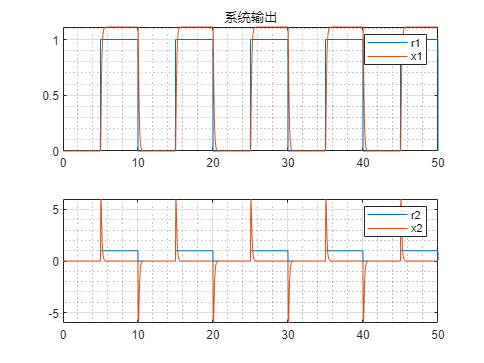

figure(1)
subplot(2, 1, 1)
plot (t, r(1,:), t, X_k(1,:));
title("系统输出")
legend("r1","x1")
grid on
grid minor

subplot(2, 1, 2)
plot (t, r(2,:), t, X_k(2,:));
legend("r2","x2")
grid on
grid minor

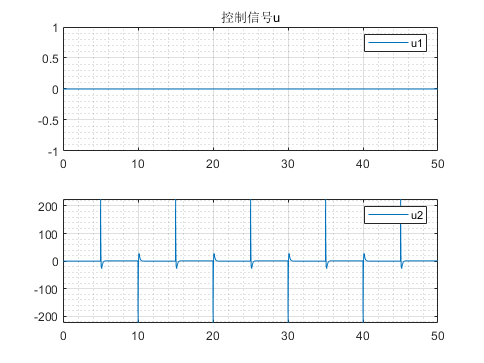


figure(2)
subplot(2, 1, 1)
plot(t(2:length(t)), U_k(1,:))
title("控制信号u")
legend("u1")
grid on
grid minor
subplot(2, 1, 2)
plot(t(2:length(t)), U_k(2,:))
legend("u2")
grid on
grid minor